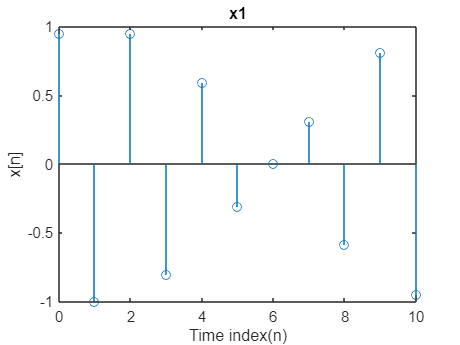

clc, close all; clear;

% P-4.2 
% x1
n=0:1:10;
x1=cos(0.9.*pi.*n+0.1.*pi);
stem(n,x1);
title('x1');xlabel('Time index(n)');ylabel('x[n]')

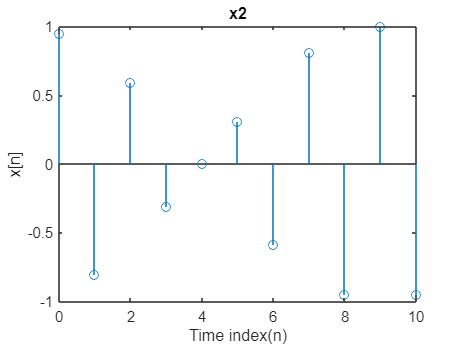

% x2
x2=cos(-2.9.*pi.*n+0.1.*pi);
stem(n,x2);
title('x2');
xlabel('Time index(n)');
ylabel('x[n]');

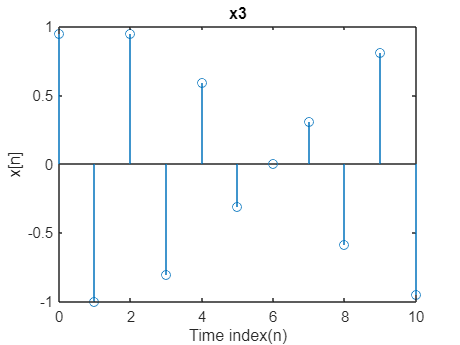

% x3
x3=cos(5.1.*pi.*n-0.1.*pi);
stem(n,x3);
title('x3');
xlabel('Time index(n)');
ylabel('x[n]');

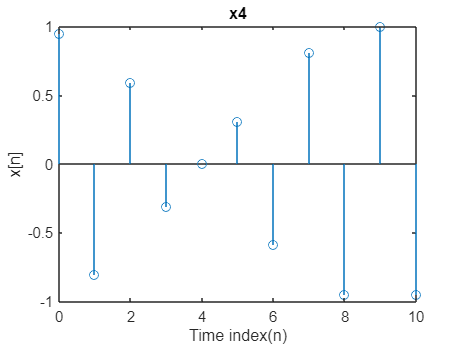

% x4
x4=cos(6.9.*pi.*n-0.1.*pi);
stem(n,x4);
title('x4');
xlabel('Time index(n)');
ylabel('x[n]');

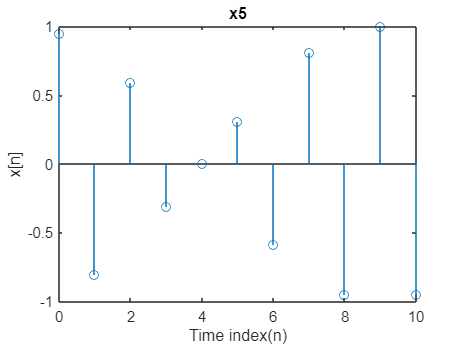

% x5
x5=cos(-7.1.*pi.*n-0.1.*pi);
stem(n,x5);
title('x5');
xlabel('Time index(n)');
ylabel('x[n]');

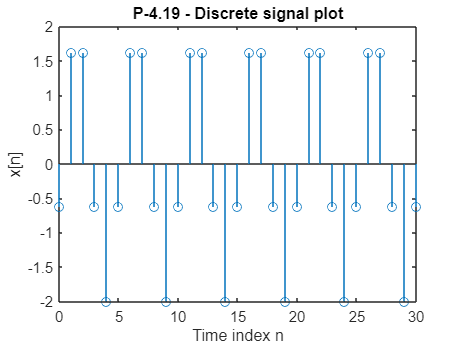

clc, close all; clear;

% P-4.19
Ts = 0.01; % units are seconds
Duration = 0.3;
tt = 0 : Ts : Duration;
Fo = 380; % units are Hz
xn = 2*cos( 2*pi*Fo*tt + 0.6*pi );
stem( 0:length(xn)-1, xn) 
title('P-4.19 - Discrete signal plot');
xlabel('Time index n');
ylabel('x[n]');

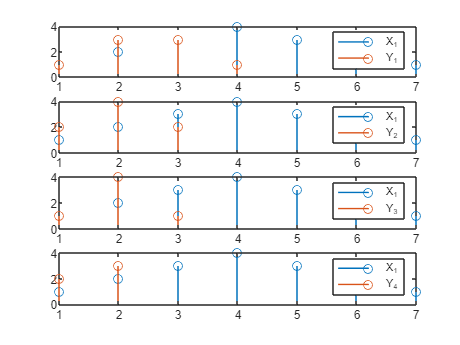

clc, close all; clear;

% 4)
X_1 = [1,2,3,4,3,2,1]; 
Y_1 = downsample(X_1,2); 
Y_2 = downsample(X_1,2,1); 
Y_3 = downsample(X_1,3); 
Y_4 = downsample(X_1,3,1); 
% Also, plot the results using "stem" command. 
% You can use subplot command for this problem.   
figure(1); subplot(411); stem(X_1); hold on; stem(Y_1); legend('X_1','Y_1');  
subplot(412); stem(X_1); hold on; stem(Y_2); legend('X_1','Y_2') 
subplot(413); stem(X_1); hold on; stem(Y_3); legend('X_1','Y_3') 
subplot(414); stem(X_1); hold on; stem(Y_4); legend('X_1','Y_4') 

clc, close all; clear;

% 5)
X_2 = [ 1 2 3 4]; 
Y_1 = upsample(X_2,2); 
Y_2 = upsample(X_2,2,1); 
Y_3 = upsample(X_2,3);
Y_4 = upsample(X_2,3,1); 
Y_5 = upsample(X_2,3,2);
figure(1); subplot(511); stem(X_2); hold on; stem(Y_1); legend('X_2','Y_1');  
subplot(512); stem(X_2); hold on; stem(Y_2); legend('X_2','Y_2') 
subplot(513); stem(X_2); hold on; stem(Y_3); legend('X_2','Y_3') 
subplot(514); stem(X_2); hold on; stem(Y_4); legend('X_2','Y_4') 
subplot(515); stem(X_2); hold on; stem(Y_5); legend('X_2','Y_5') 


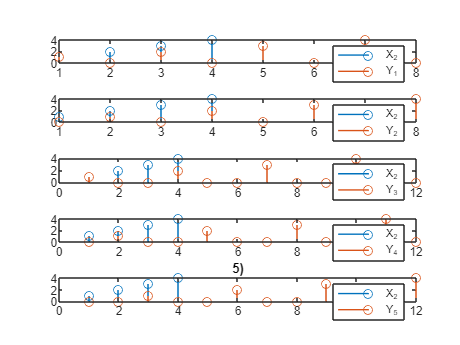

clc, close all; clear;

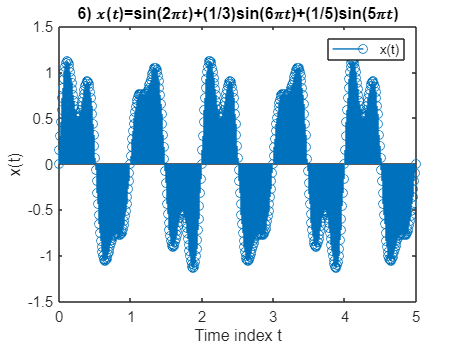


% 6)
t = 0:0.01:5;
x = sin(2*pi.*t) + (1/3)*sin(6*pi.*t) + (1/5)*sin(5*pi*t);
stem(t, x) 
title('6) 𝑥(𝑡)=sin(2𝜋𝑡)+(1/3)sin(6𝜋𝑡)+(1/5)sin (5𝜋𝑡)');
xlabel('Time index t');
ylabel('x(t)');
legend('x(t)');

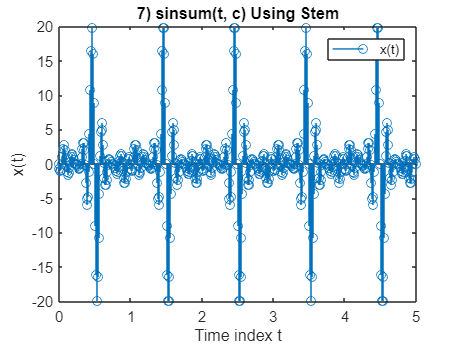

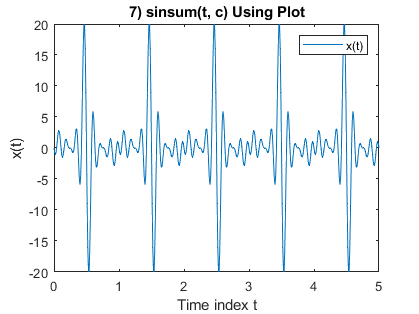

clc, close all; clear;


% 7)
t = 0:0.01:5;
c = [1, -1, 2, -2, 3, -3, 4, -4, 2, -2];
output = sinsum(t,c);


function output = sinsum(t,c)
    output = 0;
    for k = 1:10
        x = c(k)*sin(2*pi*k.*t);
        output = output + x ;
    end
    figure;
    stem(t,output)
    title('7) sinsum(t, c) Using Stem');
    xlabel('Time index t');
    ylabel('x(t)');
    legend('x(t)');
    figure;
    plot(t,output)
    title('7) sinsum(t, c) Using Plot');
    xlabel('Time index t');
    ylabel('x(t)');
    legend('x(t)');
end
